Table for Time Point 1


    Region_Label     R      G      B      Area_um2     Circumference_um    Compactness
    ____________    ___    ___    ___    __________    ________________    ___________

          1           0      0    255         10654         355.06           3.3362   
          2           0      5    255          1802         145.96           3.3393   
          3           0     11    255        9679.2         346.86           3.1761   
          4           0     23    255        5416.9         247.64           3.4871   
          5           0     35    255        5395.3         350.14           1.7374   
          6           0     41    255        6358.2         309.96           2.6127   
          7           0     50    255        1705.2         132.0

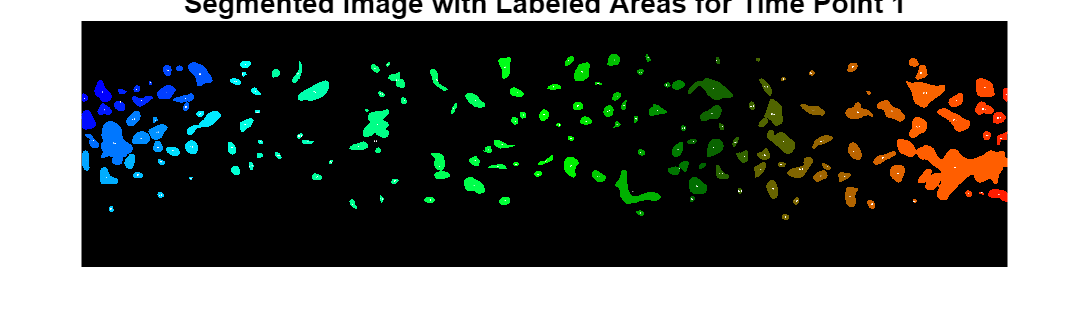

Table for Time Point 2


    Region_Label     R      G      B      Area_um2     Circumference_um    Compactness
    ____________    ___    ___    ___    __________    ________________    ___________

          1           0      0    255         15348         564.98            1.8982  
          2           0      5    255        1574.8         133.66            3.4799  
          3           0     11    255        8033.2         322.26            3.0538  
          5           0     35    255        3001.6         177.94            3.7425  
          6           0     41    255        3265.2         195.16            3.3844  
          7           0     50    255        1233.2         112.34            3.8576  
          9           0     62    255        6442.3         269.7

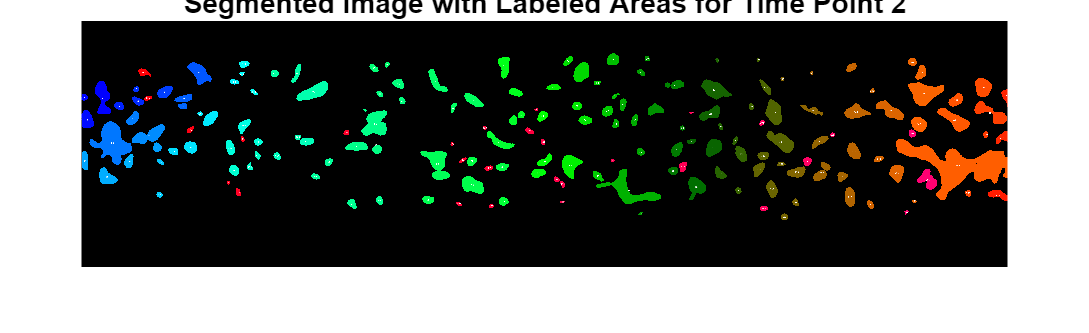

Table for Time Point 3


    Region_Label     R      G      B     Area_um2     Circumference_um    Compactness
    ____________    ___    ___    ___    _________    ________________    ___________

          1           0      0    255        12754         597.78             1.409  
          3           0     11    255       7906.8         323.08            2.9905  
          5           0     35    255       3449.4          192.7            3.6673  
          6           0     41    255         5439         300.12            2.3839  
          7           0     50    255       1071.1         124.64             2.722  
          9           0     62    255       5664.3         250.92            3.5517  
         12           0     86    255        13564         417.38        

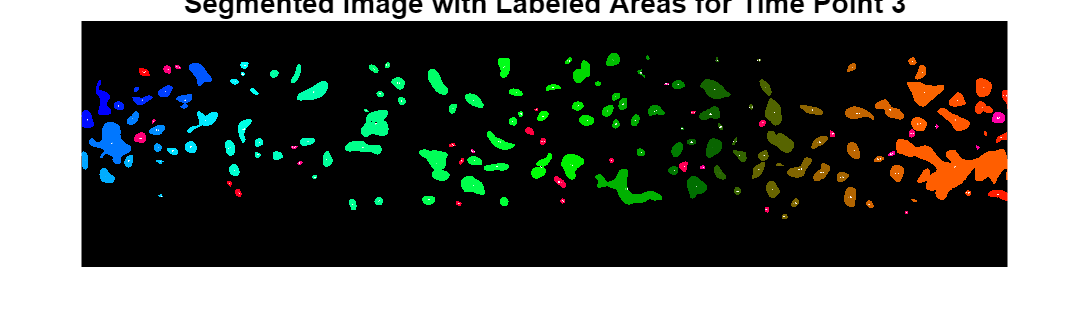

Table for Time Point 4


    Region_Label     R      G      B      Area_um2     Circumference_um    Compactness
    ____________    ___    ___    ___    __________    ________________    ___________

          1           0      0    255         10732         436.24           2.2262   
          3           0     11    255        7632.4          315.7           3.0232   
          5           0     35    255        2979.4         177.94           3.7149   
          6           0     41    255        5495.5         282.08           2.7266   
          7           0     50    255        1032.1          102.5           3.8784   
          9           0     62    255        5263.5         248.46           3.3661   
         12           0     86    255         14744         428.8

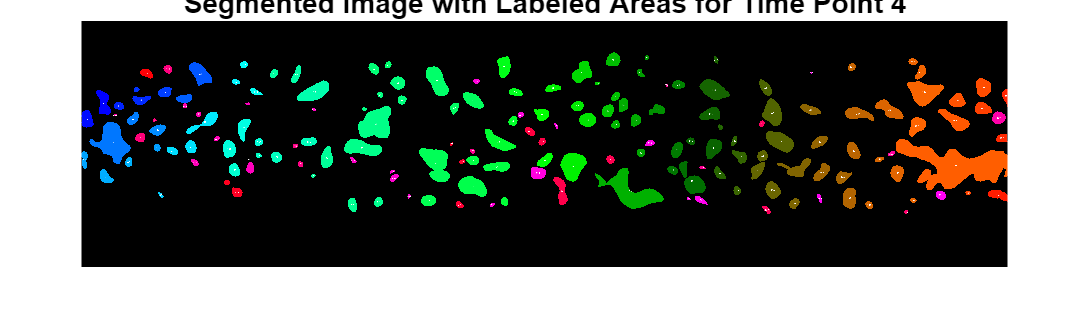

Table for Time Point 5


    Region_Label     R      G      B      Area_um2     Circumference_um    Compactness
    ____________    ___    ___    ___    __________    ________________    ___________

          1           0      0    255         10678         421.48           2.3729   
          3           0     11    255        7288.8         304.22           3.1091   
          5           0     35    255        2518.1         162.36           3.7712   
          6           0     41    255        5188.2         264.86           2.9198   
          7           0     50    255        391.34          74.62           2.7746   
          9           0     62    255        5691.9         249.28           3.6161   
         12           0     86    255         16115          430.

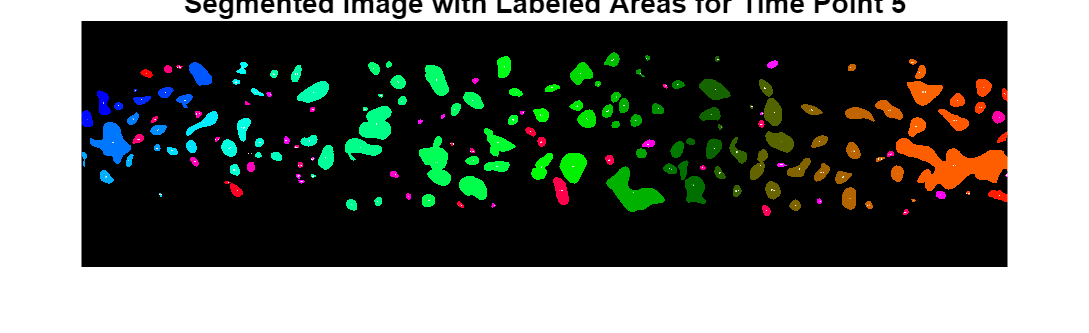

Table for Time Point 6


    Region_Label     R      G      B     Area_um2     Circumference_um    Compactness
    ____________    ___    ___    ___    _________    ________________    ___________

          1           0      0    255        11183         410.82            2.6158  
          3           0     11    255       7002.4         289.46            3.2993  
          5           0     35    255       1321.9         115.62             3.904  
          6           0     41    255       4437.8          241.9            2.9941  
          7           0     50    255       823.02         107.42            2.8158  
          9           0     62    255       5965.5         253.38            3.6683  
         12           0     86    255        15991         421.48        

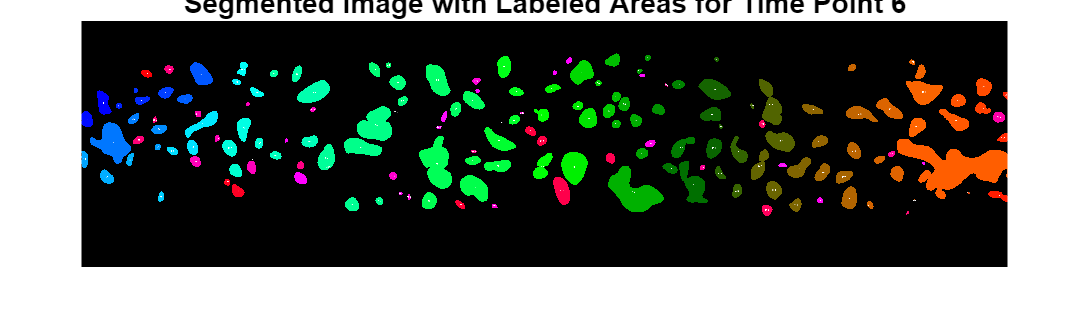

Table for Time Point 7


    Region_Label     R      G      B      Area_um2     Circumference_um    Compactness
    ____________    ___    ___    ___    __________    ________________    ___________

          1           0      0    255         11451         405.08             2.755  
          3           0     11    255        6397.9         277.16             3.288  
          5           0     35    255        1313.2         113.16            4.0486  
          6           0     41    255          4538         239.44            3.1249  
          9           0     62    255        5875.4         249.28            3.7327  
         12           0     86    255         16875         429.68            3.6084  
         13           0     95    255        5069.2         245.1

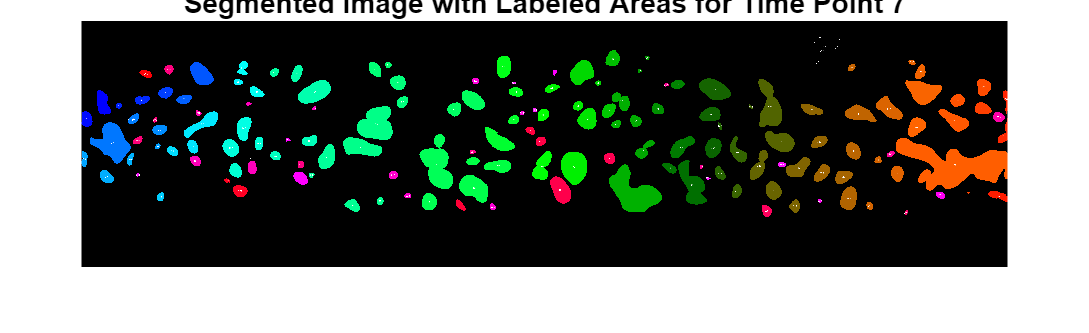

%%% ----- Time tracking and analysis tool for lab on a chip septup masks --- by Tommy

%%% ---- Segmentation of masks over time based on RGB values, only works with .png
% files with 32 bit depth
% updated for whole chip, this is version 1.4

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% First part is doing the labelling of the clusters according to the RGB
%%% values over time. Images need to be already segmented and have
%%% different RGB values for every cluster, that should be differentiated


% Conversion factor: 1 pixel = 0.6724 square micrometers
conversion_factor = 0.6724;  % µm² per pixel
pixel_to_micrometer = sqrt(conversion_factor);  
rgb_label_mapping = [];  
current_label_count = 0;  

%can do it with any number of timepoints, I just used it for 7 so far

file_names = { ...
    '01.png', ...
    '02.png', ...
    '03.png', ...
    '04.png', ...
    '05.png', ...
    '06.png', ...
    '07.png', ...

};

% RGB value to exclude --- grey (I want to filter out the border regions)
exclude_rgb = [128, 128, 128];

num_time_points = length(file_names);

% Loop over each time point
for t = 1:num_time_points
    
    input_image = imread(file_names{t});
    
    
    if size(input_image, 3) ~= 3
        error('Image at time point %d is not RGB. Please check the input file.', t);
    end
    
    
    [rows, cols, ~] = size(input_image);
  
    reshaped_image = reshape(input_image, [], 3);
    
    [unique_colors, ~, labels] = unique(reshaped_image, 'rows');
   
    labeled_image = reshape(labels, [rows, cols]);
    
    
    significant_labeled_image = zeros(size(input_image), 'uint8');  
    
    % Set the threshold -> removes regions, that do not fit (too small and
    % too big ones, but if the mask is done properly there should not be
    % any)
    pixel_min_threshold = 100;  
    pixel_max_threshold = 4.3309e+05;  
    
    % Initialize matrices to store pixel counts, areas, circumferences, compactness, and region labels
    pixel_counts = [];            
    areas_um2 = [];               
    circumferences_um = [];       
    compactnesses = [];           
    region_labels = [];           
    rgb_values = [];              

    % Loop through each unique region and count pixels
    for label_val = 1:max(labeled_image(:))
        
        mask = (labeled_image == label_val);
        
        
        pixel_count = sum(mask(:));
        
        
        [r, c] = find(mask);  
        if isempty(r) || isempty(c)
            continue;
        end
        
        
        current_rgb = reshape(input_image(r(1), c(1), :), 1, 3);
        
        % Skip the region if it has the RGB value [128, 128, 128] -> no
        % border
        if all(current_rgb == exclude_rgb)
            continue;
        end
        
        % Check if the region size is within the defined thresholds
        if pixel_count >= pixel_min_threshold && pixel_count <= pixel_max_threshold
            % Check if the RGB value already has an assigned label
            if isempty(rgb_label_mapping)
                % If rgb_label_mapping is empty, assign the first label
                is_existing_rgb = false;
            else
                % Check if this RGB value already has an assigned label
                [is_existing_rgb, existing_label_index] = ismember(current_rgb, rgb_label_mapping(:, 1:3), 'rows');
            end
            
            if is_existing_rgb
                
                region_label = rgb_label_mapping(existing_label_index, 4);
            else
                % Assign a new label if this RGB value is new -> new
                % cluster in case of angiogenesis
                current_label_count = current_label_count + 1;
                region_label = current_label_count;
                rgb_label_mapping = [rgb_label_mapping; current_rgb, region_label];  % Add new RGB and label to mapping
            end
            
            
            region_labels = [region_labels; region_label];
            rgb_values = [rgb_values; current_rgb]; 
            
            
            area_um2 = pixel_count * conversion_factor;  
            areas_um2 = [areas_um2; area_um2];
            
            
            perimeter_mask = bwperim(mask);
            circumference_pixels = sum(perimeter_mask(:));  
            
            
            circumference_um = circumference_pixels * pixel_to_micrometer;  
            circumferences_um = [circumferences_um; circumference_um];
            
            
            if circumference_um > 0
                compactness = area_um2 / ( (circumference_um / (2 * pi)) ^ 2 );
            else
                compactness = NaN;  % Avoid division by zero if circumference is zero
            end
            compactnesses = [compactnesses; compactness];
            
            % Calculate the centroid for placing the label
            centroid_r = round(mean(r));
            centroid_c = round(mean(c));
            
            
            significant_labeled_image(repmat(mask, [1, 1, 3])) = input_image(repmat(mask, [1, 1, 3]));
            
            
            significant_labeled_image = insertText(significant_labeled_image, [centroid_c, centroid_r], ...
                                                   num2str(region_label), 'TextColor', 'white', ...
                                                   'BoxOpacity', 0, 'FontSize', 18, 'AnchorPoint', 'Center');
        end
    end
    
    %saving it as png again, so that it can be used further with the
    %labels

    imwrite(significant_labeled_image, sprintf('significant_labeled_areas_timepoint_%d.png', t)); 
    
    

    %Output tables with each cluster having a region label based on RGB
    %combination and also with area, circumference and compactness
    output_table = table(region_labels, rgb_values(:,1), rgb_values(:,2), rgb_values(:,3), ...
        areas_um2, circumferences_um, compactnesses, ...
        'VariableNames', {'Region_Label', 'R', 'G', 'B', 'Area_um2', 'Circumference_um', 'Compactness'});
    
    
    disp(sprintf('Table for Time Point %d', t));
    disp(output_table);
    
    
    writetable(output_table, sprintf('regions_rgb_area_circumference_compactness_timepoint_%d.csv', t));
    
    
    figure;
    imshow(significant_labeled_image);
    title(sprintf('Segmented Image with Labeled Areas for Time Point %d', t));
    
end  % End of time point loop

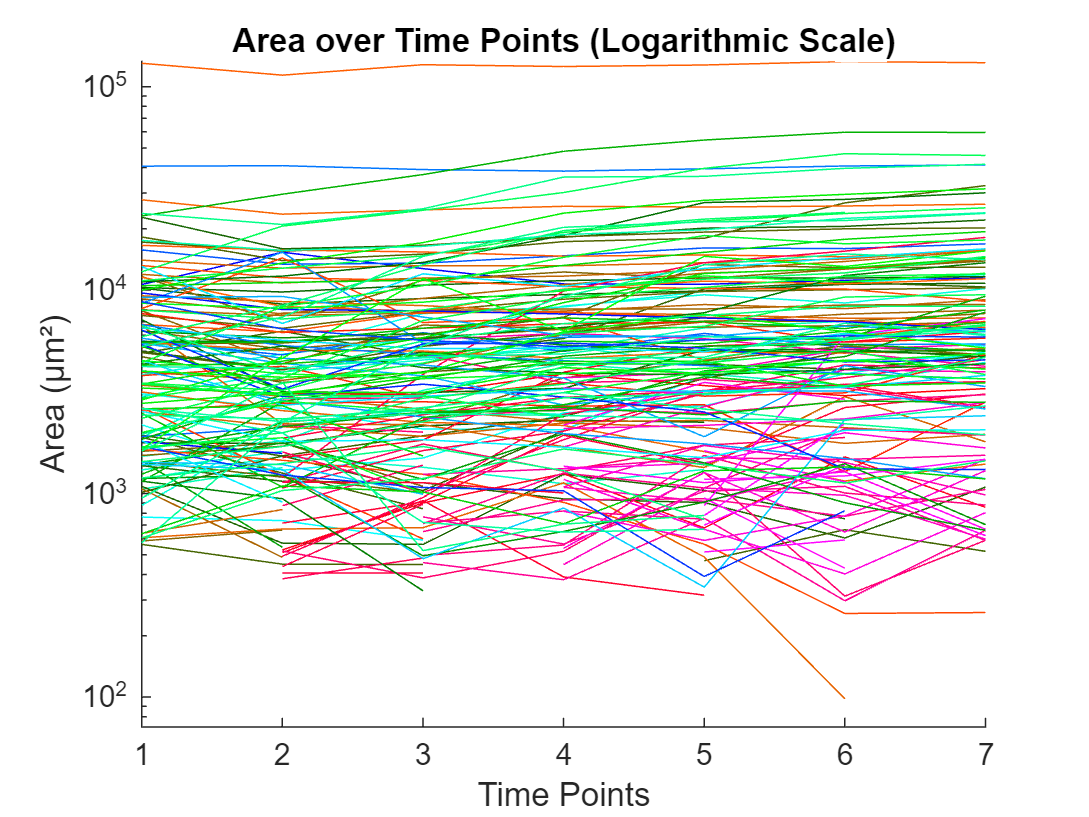



%%%% Cluster tracking and labelling is done at that point, next parts are
%%%% diagrams and data analysis


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%%%% diagram generation part 1

%this is supposed to show all individual clusters with their parameters
%over time ... this gets very crowded if the whole chip has alot of
%clusters and not only one ROI is analysed ...


%First part gets the values from the tables and organizes them

num_time_points = length(file_names);

% Initialize Area, Circumference, and Compactness over time
areas_over_time = containers.Map();
circumferences_over_time = containers.Map();
compactness_over_time = containers.Map();
rgb_colors = containers.Map();  

% processing each time point
for t = 1:num_time_points
    
    table_filename = sprintf('regions_rgb_area_circumference_compactness_timepoint_%d.csv', t);
    data_table = readtable(table_filename);

    % Loop through each region (row) in the table
    for i = 1:height(data_table)
        region_label = num2str(data_table.Region_Label(i));  % Convert the region label to string for use as a key
        area_value = data_table.Area_um2(i);
        circumference_value = data_table.Circumference_um(i);
        compactness_value = data_table.Compactness(i);
        rgb_value = [data_table.R(i), data_table.G(i), data_table.B(i)];
        
        
        if ~isKey(areas_over_time, region_label)
            areas_over_time(region_label) = NaN(1, num_time_points);
            circumferences_over_time(region_label) = NaN(1, num_time_points);
            compactness_over_time(region_label) = NaN(1, num_time_points);
            rgb_colors(region_label) = rgb_value;
        end
        
        % Getting the current array from the map, update it, and store it back
        area_array = areas_over_time(region_label);
        area_array(t) = area_value;
        areas_over_time(region_label) = area_array;
        
        circumference_array = circumferences_over_time(region_label);
        circumference_array(t) = circumference_value;
        circumferences_over_time(region_label) = circumference_array;
        
        compactness_array = compactness_over_time(region_label);
        compactness_array(t) = compactness_value;
        compactness_over_time(region_label) = compactness_array;
    end
end

% Now plot the diagrams

% I used for this case logarithmic scales for the parameters, since there
% are some very big clusters, and they really shift everything heavily so
% that you can't see the smaller or average clusters


time_points = 1:num_time_points;

%      Plot for Area
figure;
hold on;
title('Area over Time Points (Logarithmic Scale)');
xlabel('Time Points');
ylabel('Area (µm²)');
set(gca, 'YScale', 'log');
keys_regions = keys(areas_over_time);
for i = 1:length(keys_regions)
    region_label = keys_regions{i};
    rgb_value = rgb_colors(region_label) / 255;
    plot(time_points, areas_over_time(region_label), 'Color', rgb_value, 'LineWidth', 0.5);
end
hold off;

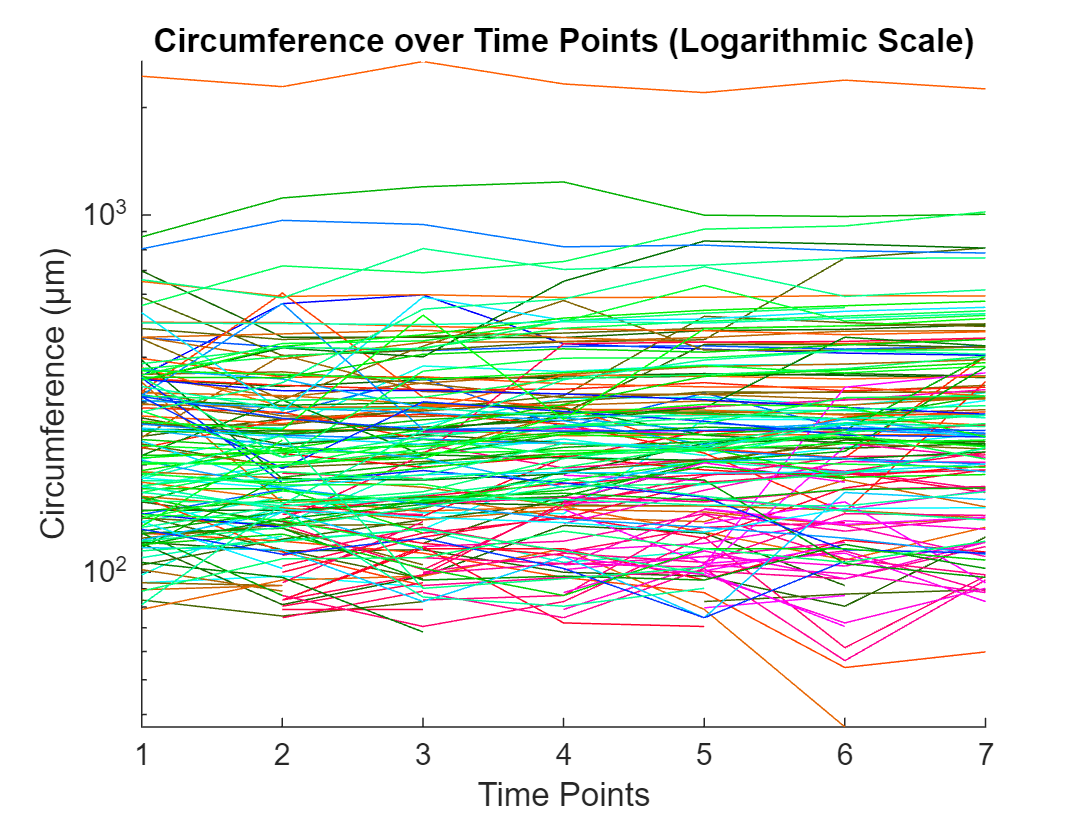


%     Plot for Circumference
figure;
hold on;
title('Circumference over Time Points (Logarithmic Scale)');
xlabel('Time Points');
ylabel('Circumference (µm)');
set(gca, 'YScale', 'log');
for i = 1:length(keys_regions)
    region_label = keys_regions{i};
    rgb_value = rgb_colors(region_label) / 255;
    plot(time_points, circumferences_over_time(region_label), 'Color', rgb_value, 'LineWidth', 0.5);
end
hold off;

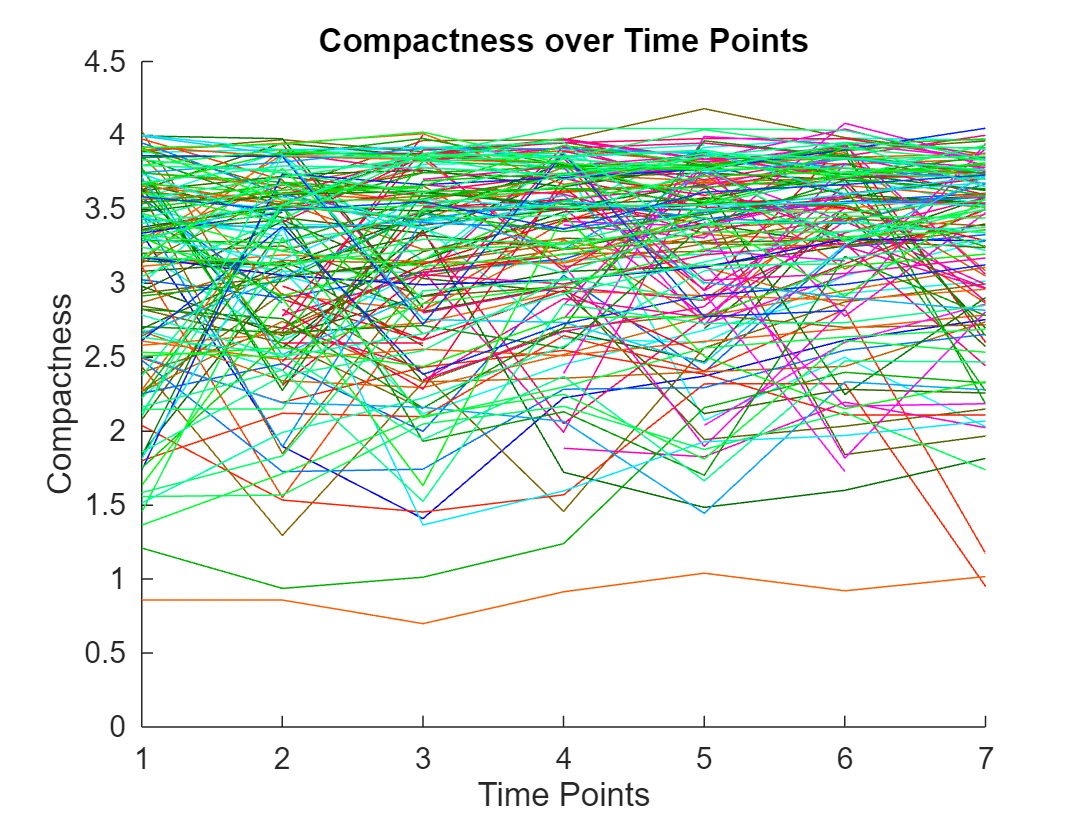


%    Plot for Compactness 
figure;
hold on;
title('Compactness over Time Points');
xlabel('Time Points');
ylabel('Compactness');
for i = 1:length(keys_regions)
    region_label = keys_regions{i};
    rgb_value = rgb_colors(region_label) / 255;
    plot(time_points, compactness_over_time(region_label), 'Color', rgb_value, 'LineWidth', 0.5);
end
hold off;

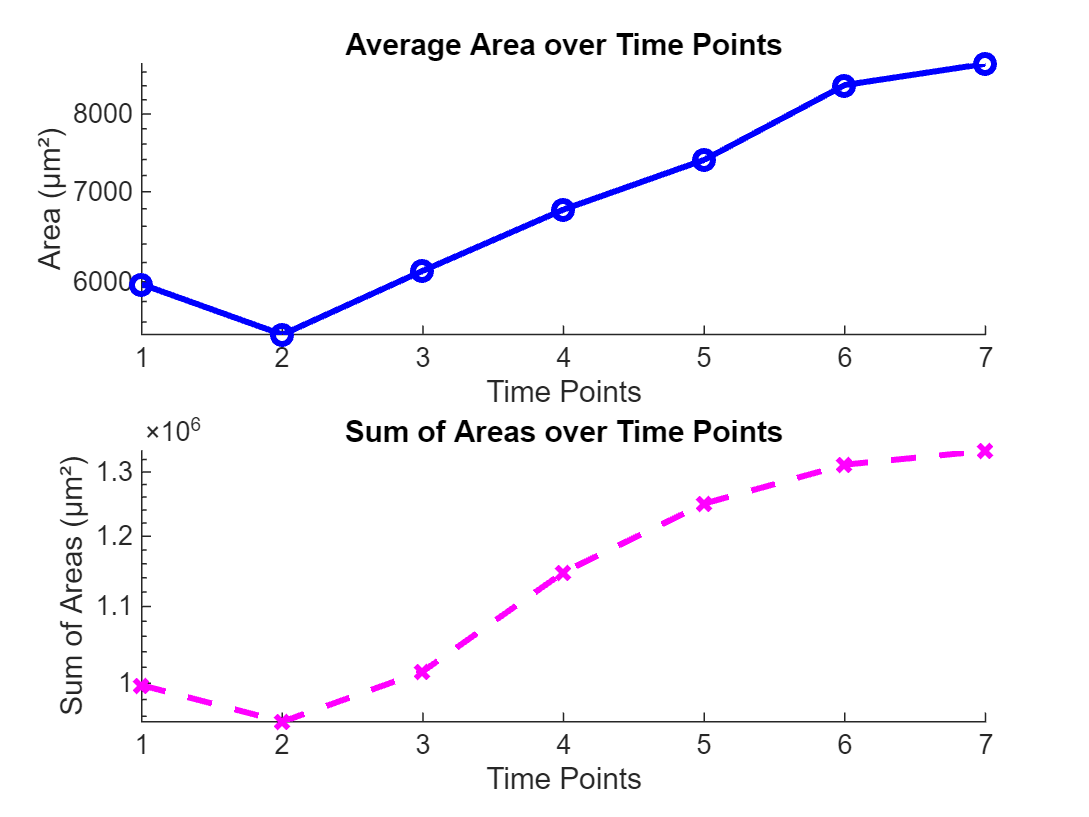





%For the next diagrams, we calculate averages and normalized values, since
%these are actually useful for interpretation

% arrays created
avg_areas = NaN(1, num_time_points);
sum_areas = NaN(1, num_time_points);
normalized_avg_areas = NaN(1, num_time_points);

avg_circumferences = NaN(1, num_time_points);
sum_circumferences = NaN(1, num_time_points);
normalized_avg_circumferences = NaN(1, num_time_points);

avg_compactnesses = NaN(1, num_time_points);
normalized_avg_compactnesses = NaN(1, num_time_points);

% Calculate average, sum, and normalized values for each time point
for t = 1:num_time_points
    total_area = 0;
    total_circumference = 0;
    total_compactness = 0;
    
    area_values = [];
    circumference_values = [];
    compactness_values = [];
    
    % Loop through every region
    for i = 1:length(keys_regions)
        region_label = keys_regions{i};
        
        area_array = areas_over_time(region_label);
        circumference_array = circumferences_over_time(region_label);
        compactness_array = compactness_over_time(region_label);
        
        if ~isnan(area_array(t))
            area_values = [area_values, area_array(t)];
            total_area = total_area + area_array(t);
        end
        
        if ~isnan(circumference_array(t))
            circumference_values = [circumference_values, circumference_array(t)];
            total_circumference = total_circumference + circumference_array(t);
        end
        
        if ~isnan(compactness_array(t))
            compactness_values = [compactness_values, compactness_array(t)];
        end
    end
    
    % Average and normalized values
    if ~isempty(area_values)
        avg_areas(t) = mean(area_values);
        sum_areas(t) = total_area;
        normalized_avg_areas(t) = avg_areas(t) / length(area_values);
    end
    
    if ~isempty(circumference_values)
        avg_circumferences(t) = mean(circumference_values);
        sum_circumferences(t) = total_circumference;
        normalized_avg_circumferences(t) = avg_circumferences(t) / length(circumference_values);
    end
    
    if ~isempty(compactness_values)
        avg_compactnesses(t) = mean(compactness_values);
        normalized_avg_compactnesses(t) = avg_compactnesses(t) / length(compactness_values);
    end
end

% Plotting now the average values and sums and normalization (in the case
% of compactness)

% Plot Area (with average and sum only, no normalization)
figure;

% Subplot 1: Average Area
subplot(2, 1, 1);
hold on;
title('Average Area over Time Points');
xlabel('Time Points');
ylabel('Area (µm²)');
set(gca, 'YScale', 'log');  
plot(time_points, avg_areas, '-o', 'LineWidth', 2, 'Color', 'b'); 
hold off;

% Subplot 2: Sum of Areas
subplot(2, 1, 2);
hold on;
title('Sum of Areas over Time Points');
xlabel('Time Points');
ylabel('Sum of Areas (µm²)');
set(gca, 'YScale', 'log');  
plot(time_points, sum_areas, '--x', 'LineWidth', 2, 'Color', 'm'); 
hold off;

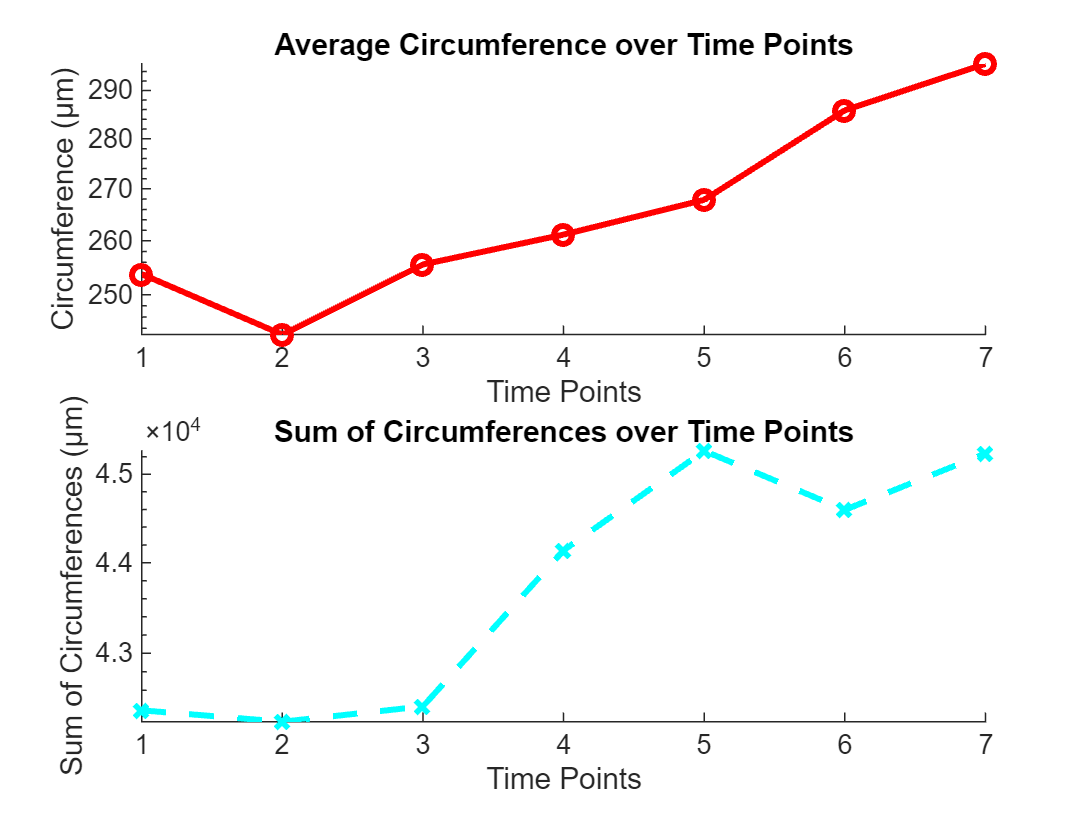




% Plot Circumference (same)
figure;

% Subplot 1: Average Circumference
subplot(2, 1, 1);
hold on;
title('Average Circumference over Time Points');
xlabel('Time Points');
ylabel('Circumference (µm)');
set(gca, 'YScale', 'log');  
plot(time_points, avg_circumferences, '-o', 'LineWidth', 2, 'Color', 'r'); 
hold off;

% Subplot 2: Sum of Circumferences
subplot(2, 1, 2);
hold on;
title('Sum of Circumferences over Time Points');
xlabel('Time Points');
ylabel('Sum of Circumferences (µm)');
set(gca, 'YScale', 'log');  
plot(time_points, sum_circumferences, '--x', 'LineWidth', 2, 'Color', 'c');  
hold off;

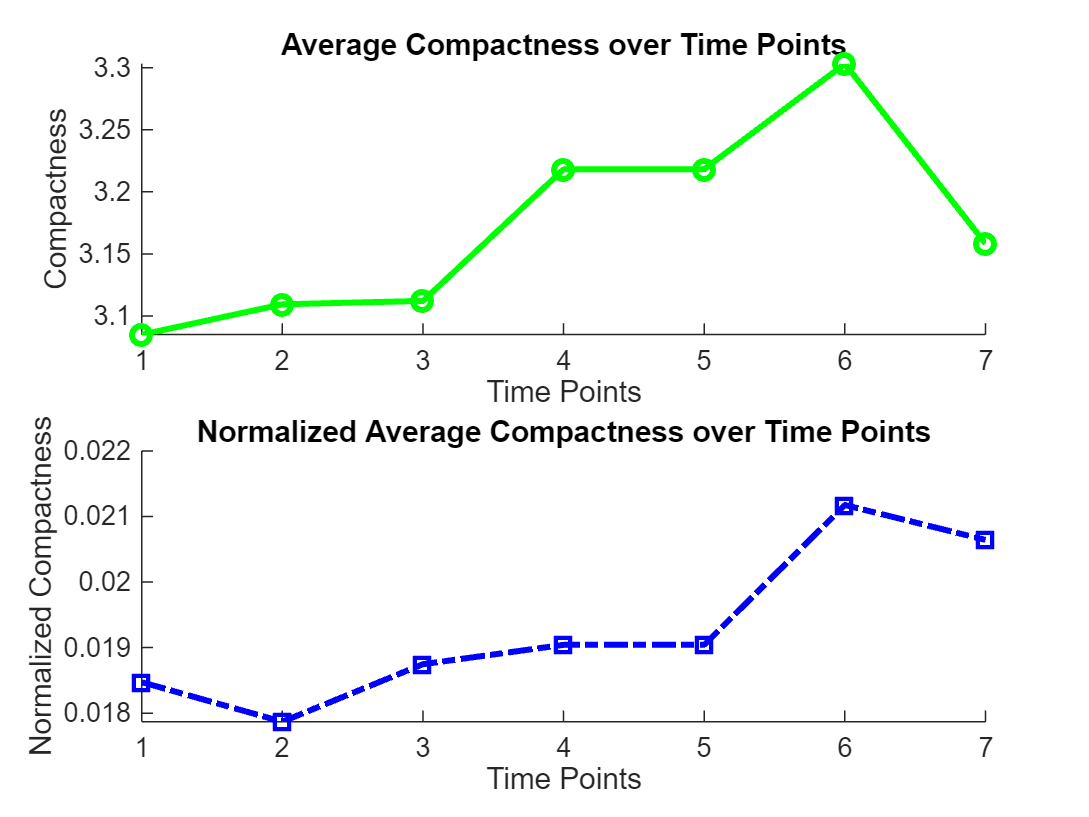





% Plot Compactness (Average and Normalized Average)
figure;

% Subplot 1: Average Compactness
subplot(2, 1, 1);
hold on;
title('Average Compactness over Time Points');
xlabel('Time Points');
ylabel('Compactness');
plot(time_points, avg_compactnesses, '-o', 'LineWidth', 2, 'Color', 'g');  % Green line for average compactness
hold off;

% Subplot 2: Normalized Average Compactness
subplot(2, 1, 2);
hold on;
title('Normalized Average Compactness over Time Points');
xlabel('Time Points');
ylabel('Normalized Compactness');
plot(time_points, normalized_avg_compactnesses, '-.s', 'LineWidth', 2, 'Color', 'b');  
hold off;

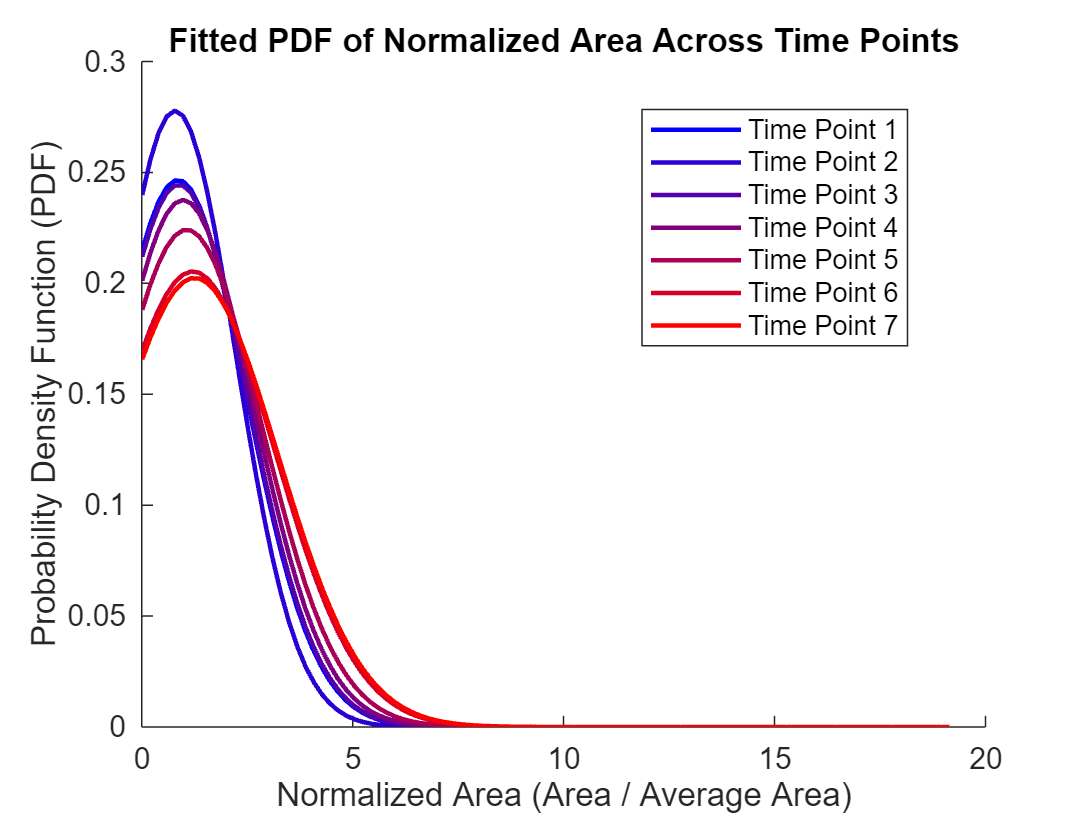





%%%% Next part is creating a probability density function


all_areas = [];
time_labels = [];

for t = 1:num_time_points
    
    data = readtable(sprintf('regions_rgb_area_circumference_compactness_timepoint_%d.csv', t));
    areas = data.Area_um2;
    all_areas = [all_areas; areas];
    time_labels = [time_labels; t * ones(size(areas))];
end

% Calculate the average area across all time points
average_area = mean(all_areas);
normalized_areas = all_areas / average_area;


figure;
hold on;

color_map = [linspace(0, 1, num_time_points)', zeros(num_time_points, 1), linspace(1, 0, num_time_points)'];

% Define the range of x-values
x_values = linspace(min(normalized_areas), max(normalized_areas), 100);

for t = 1:num_time_points
    
    current_areas = normalized_areas(time_labels == t);

    
    pd = fitdist(current_areas, 'Normal'); 
    
    
    pdf_values = pdf(pd, x_values);

    
    plot(x_values, pdf_values, 'LineWidth', 1.5, 'Color', color_map(t, :));
end

% No logarithmic x-axis, standard linear axis is used now

xlabel('Normalized Area (Area / Average Area)');
ylabel('Probability Density Function (PDF)');
title('Fitted PDF of Normalized Area Across Time Points');
legend(arrayfun(@(t) sprintf('Time Point %d', t), 1:num_time_points, 'UniformOutput', false), ...
       'Location', 'Best');

hold off;

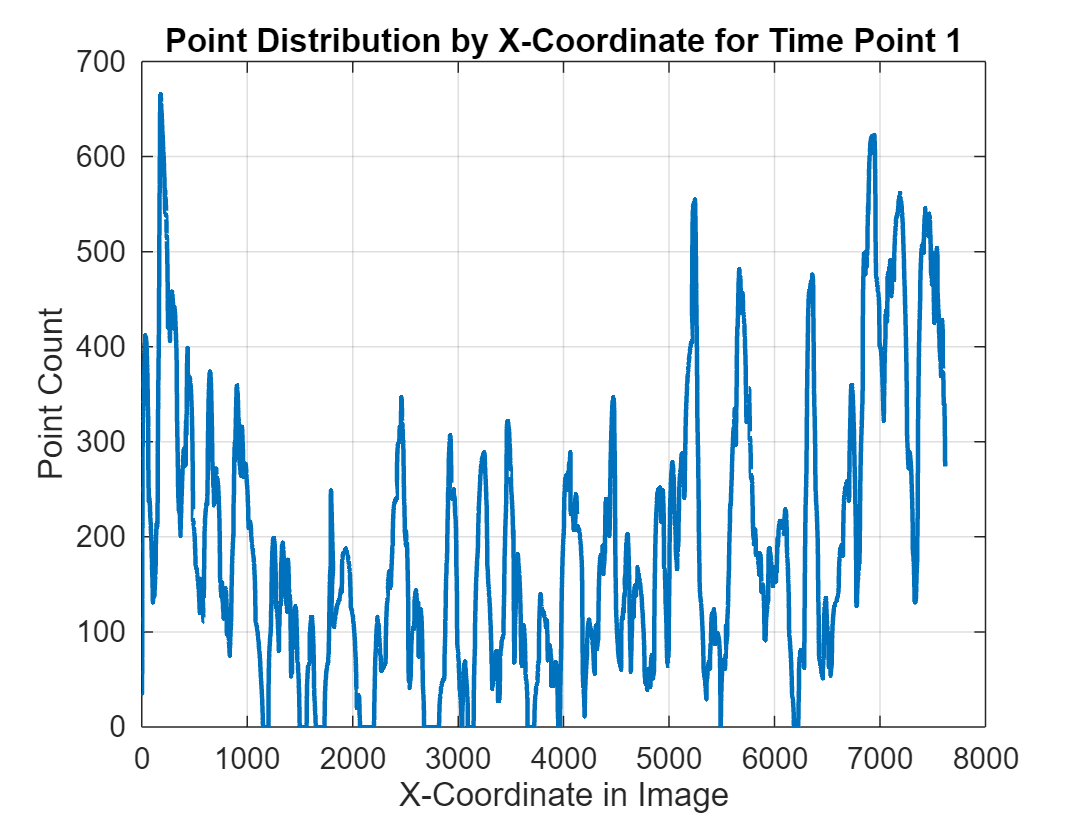

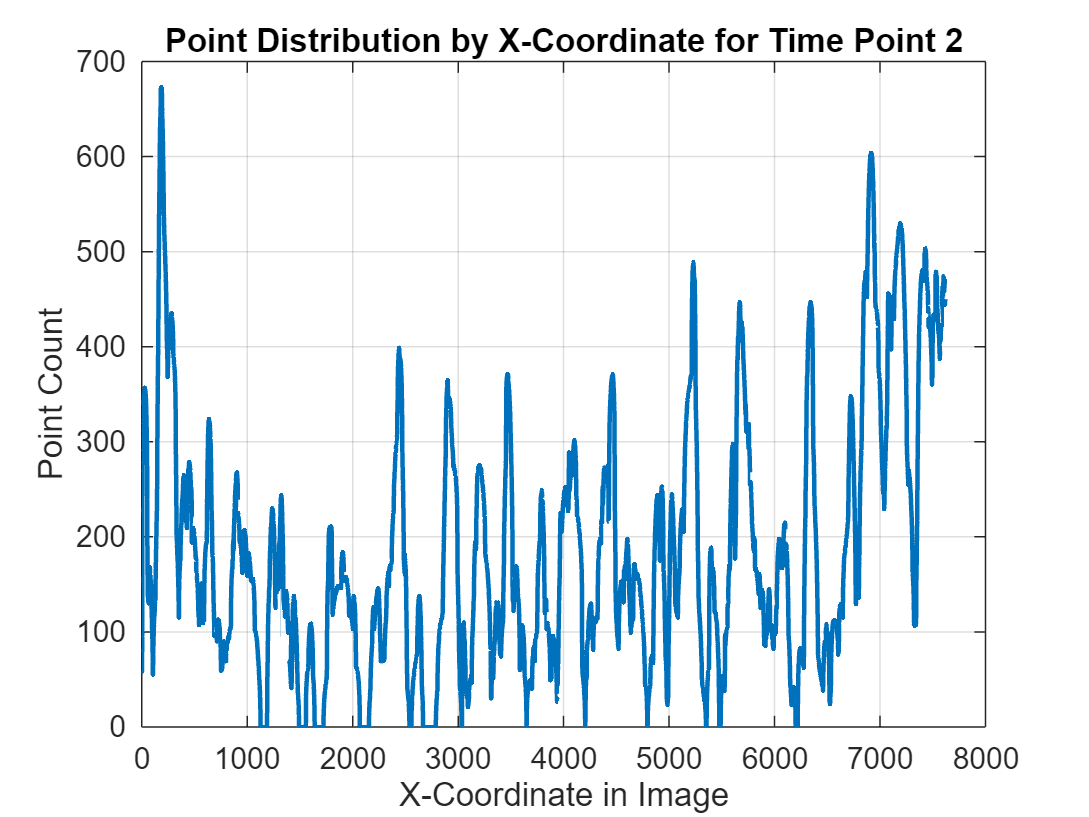

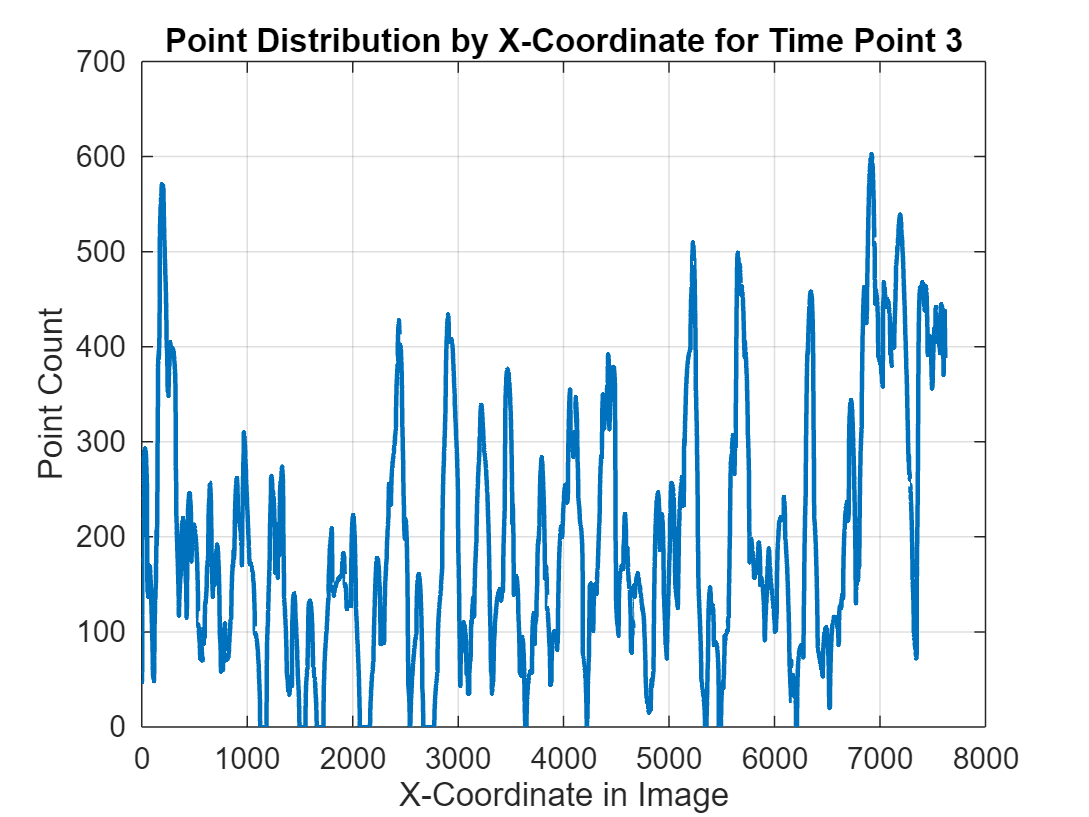

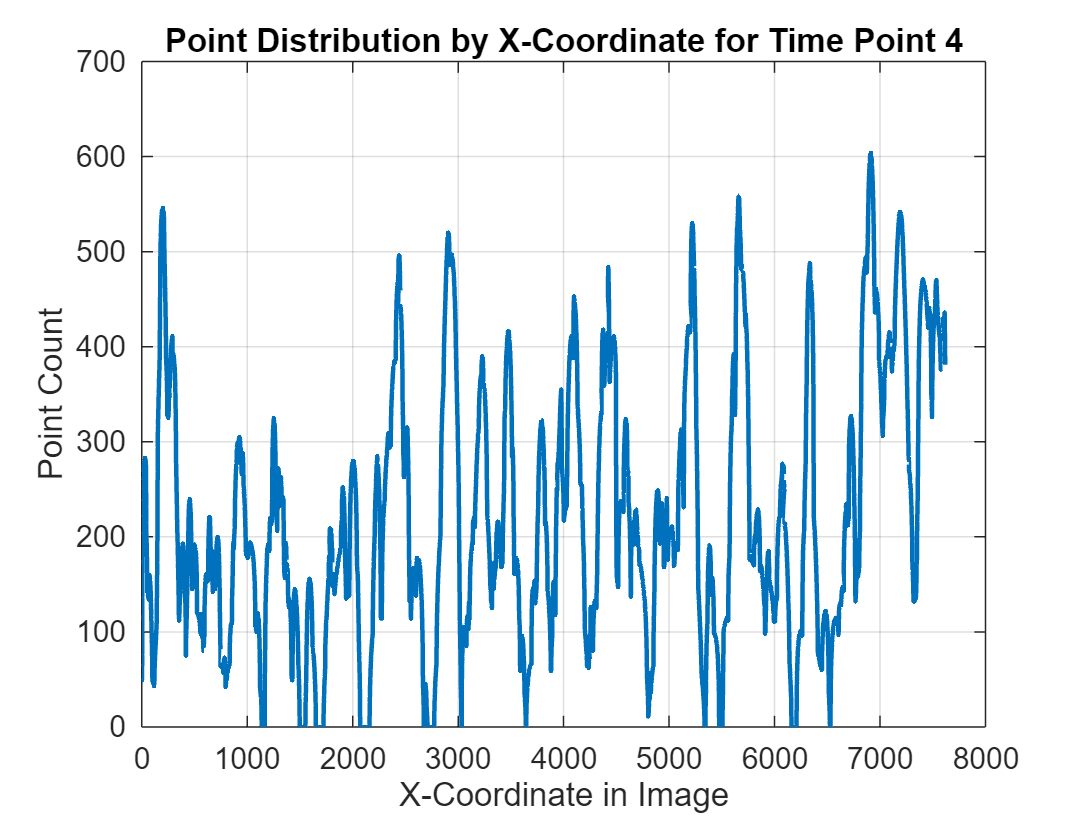

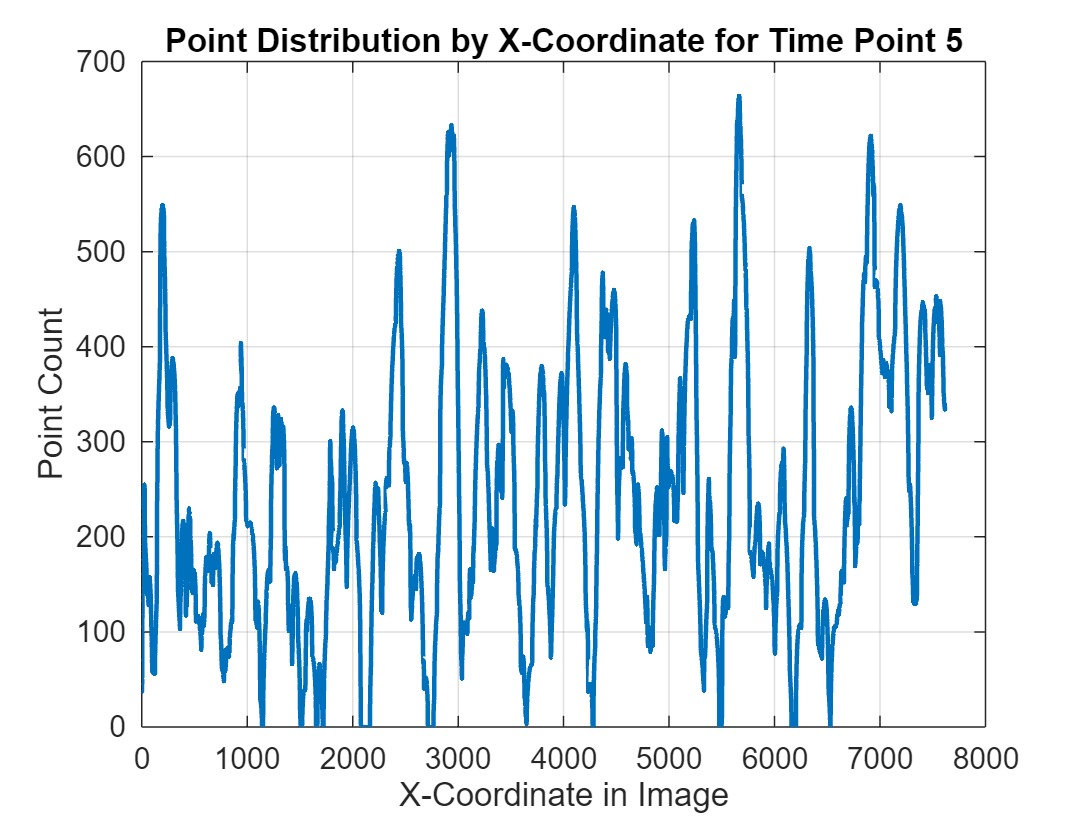

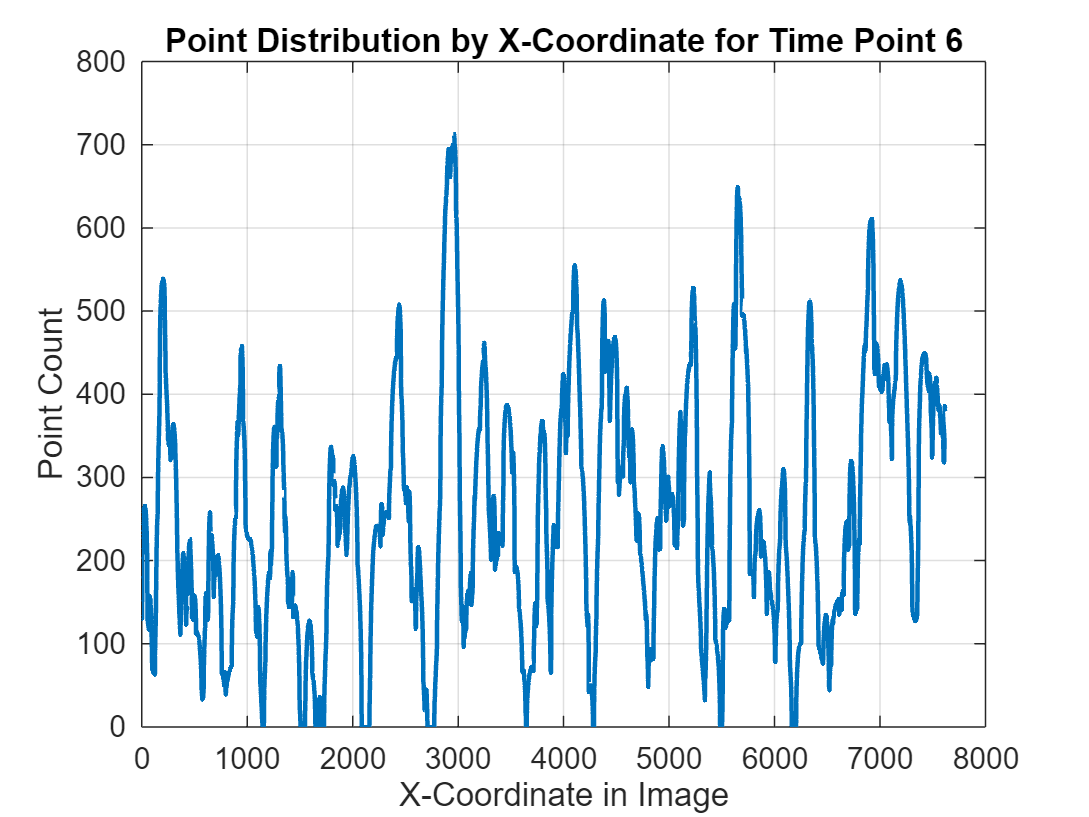

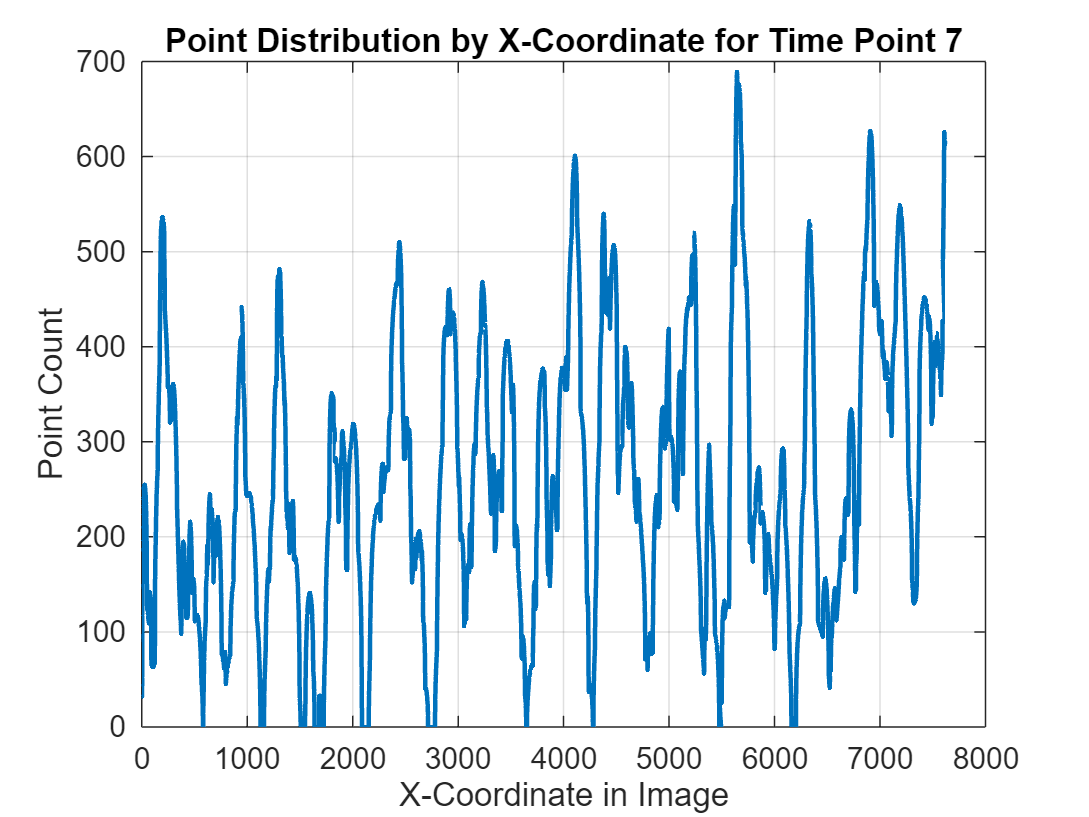






%%%% Point distribution

% This is supposed to show in a reduced dimension only alongside its x-axis
% we can see then how the area is distributed alongside the x-axis
% is used later on for the event detection, that we also have a
% distribution alongside the x-axis -> can be used to see differences in
% high flow and low flow zone


%it works by slicing the image, so taking every x coordinate and look for
%every y-coordinate, if there is a RGB value =/= 0 0 0, if yes a counter is
%added


for t = 1:numel(file_names)
    
    input_image = imread(file_names{t});
    
   
    [rows, cols, ~] = size(input_image);
    
    
    point_count_by_x = zeros(1, cols);
    
    
    for x = 1:cols
        
        column_rgb_values = input_image(:, x, :);
        
        
        column_rgb_values = reshape(column_rgb_values, rows, 3);
        
        % Check if pixels are not grayscale (where R = G = B)
        is_valid_pixel = ~(column_rgb_values(:, 1) == column_rgb_values(:, 2) & ...
                           column_rgb_values(:, 2) == column_rgb_values(:, 3));

        % Count the number of valid pixels in this x-coordinate slice
        point_count_by_x(x) = sum(is_valid_pixel);
    end

    
    point_counts_all_timepoints{t} = point_count_by_x;

     
    figure;
    plot(1:cols, point_count_by_x, 'LineWidth', 1.5);
    xlabel('X-Coordinate in Image');
    ylabel('Point Count');
    title(sprintf('Point Distribution by X-Coordinate for Time Point %d', t));
    grid on;
end

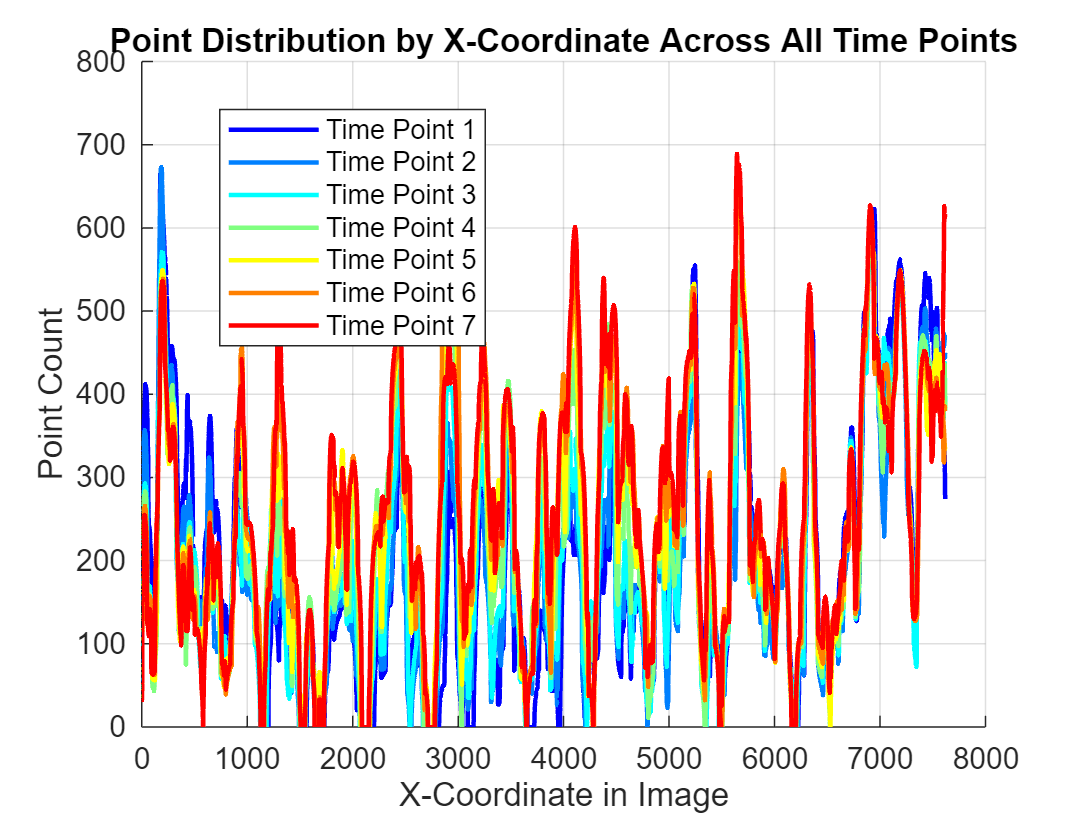



%last figure is for all timepoints combined, can be a little messy

figure;
hold on;


color_map = jet(numel(file_names));  

for t = 1:numel(file_names)
    plot(1:cols, point_counts_all_timepoints{t}, 'LineWidth', 1.5, 'Color', color_map(t, :), ...
         'DisplayName', sprintf('Time Point %d', t));
end


xlabel('X-Coordinate in Image');
ylabel('Point Count');
title('Point Distribution by X-Coordinate Across All Time Points');
legend('Location', 'Best');
grid on;
hold off;



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%